%import my downloaded training data
training = readtable("new_training_data.csv")

training = 163×18 table
     Country      ISO3166_1Alpha_3    UNM49    Year     Total      Coal      Oil    Gas    Cement    Flaring    Other    PerCapita    Var13    Var14    Var15    Population    logTotal    linDetrended
    __________    ________________    _____    ____    _______    _______    ___    ___    ______    _______    _____    _________    _____    _____    _____    __________    ________

testing = readtable("new_testing_data.csv")

testing = 5×16 table
     Country      ISO3166_1Alpha_3    UNM49    Year    Total      Coal      Oil       Gas      Cement    Flaring    Other    PerCapita    Var13    Var14    Var15    Population
    __________    ________________    _____    ____    ______    ______    ______    ______    ______    _______    _____    _________    _____    _____    _____    __________

    {'Brazil'}        {'BRA'}          76      2019       467    61.888    299.44 

%take the log to make the data stationary
training.logTotal = log(training.Total)

training = 163×18 table
     Country      ISO3166_1Alpha_3    UNM49    Year     Total      Coal      Oil    Gas    Cement    Flaring    Other    PerCapita    Var13    Var14    Var15    Population    logTotal    linDetrended
    __________    ________________    _____    ____    _______    _______    ___    ___    ______    _______    _____    _________    _____    _____    _____    __________    ________

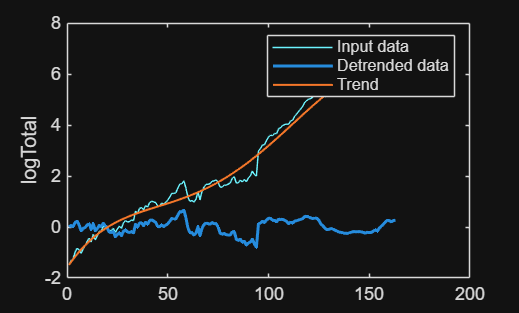

% Remove trend from input data
newTable2 = detrend(training(:,"logTotal"),4);

% Extract trend from input data
fourTrend = training(:,"logTotal");
fourTrend.(1) = fourTrend.(1) - newTable2.(1);

% Display results
figure
plot(training.logTotal,SeriesIndex=6,DisplayName="Input data")
hold on
plot(newTable2.logTotal,SeriesIndex=1,LineWidth=1.5,DisplayName="Detrended data")
plot(fourTrend.logTotal,SeriesIndex=2,LineWidth=1,DisplayName="Trend")
hold off
legend
ylabel("logTotal")

clear newTable2

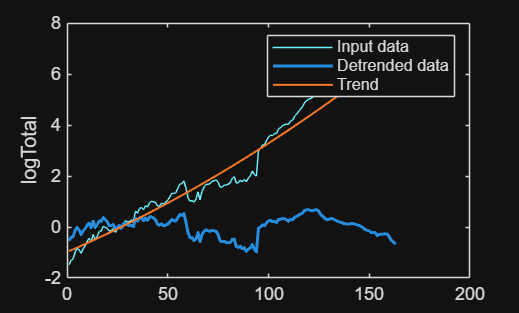

% Remove trend from input data
newTable4 = detrend(training(:,"logTotal"),2);

% Extract trend from input data
quadTrend = training(:,"logTotal");
quadTrend.(1) = quadTrend.(1) - newTable4.(1);

% Display results
figure
plot(training.logTotal,SeriesIndex=6,DisplayName="Input data")
hold on
plot(newTable4.logTotal,SeriesIndex=1,LineWidth=1.5,DisplayName="Detrended data")
plot(quadTrend.logTotal,SeriesIndex=2,LineWidth=1,DisplayName="Trend")
hold off
legend
ylabel("logTotal")

clear newTable4

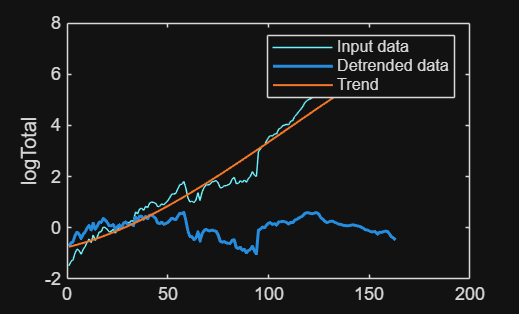

% Remove trend from input data
newTable = detrend(training(:,"logTotal"),3);

% Extract trend from input data
cubicTrend = training(:,"logTotal");
cubicTrend.(1) = cubicTrend.(1) - newTable.(1);

% Display results
figure
plot(training.logTotal,SeriesIndex=6,DisplayName="Input data")
hold on
plot(newTable.logTotal,SeriesIndex=1,LineWidth=1.5,DisplayName="Detrended data")
plot(cubicTrend.logTotal,SeriesIndex=2,LineWidth=1,DisplayName="Trend")
hold off
legend
ylabel("logTotal")

clear newTable

%compute the remainders
training.quadRemainder = training.logTotal - quadTrend.logTotal

training = 163×19 table
     Country      ISO3166_1Alpha_3    UNM49    Year     Total      Coal      Oil    Gas    Cement    Flaring    Other    PerCapita    Var13    Var14    Var15    Population    logTotal    linDetrended    quadRemainder
    __________    ________________    _____    ____    _______    _______    ___    ___    ______    _______    _____    _________    _____    _____    _____    __________</

training.cubicRemainder = training.logTotal - cubicTrend.logTotal

training = 163×20 table
     Country      ISO3166_1Alpha_3    UNM49    Year     Total      Coal      Oil    Gas    Cement    Flaring    Other    PerCapita    Var13    Var14    Var15    Population    logTotal    linDetrended    quadRemainder    cubicRemainder
    __________    ________________    _____    ____    _______    _______    ___    ___    ______    _______    _____    _________    _____    _____    ___

training.fourRemainder= training.logTotal - fourTrend.logTotal

training = 163×21 table
     Country      ISO3166_1Alpha_3    UNM49    Year     Total      Coal      Oil    Gas    Cement    Flaring    Other    PerCapita    Var13    Var14    Var15    Population    logTotal    linDetrended    quadRemainder    cubicRemainder    fourRemainder
    __________    ________________    _____    ____    _______    _______    ___    ___    ______    _______    _____    _________    _____    

%create a table to store all of the components
allComponents = table


allComponents =

  0×0 empty table



allComponents.time = training.Year

allComponents = 163×1 table
    time
    ____

    1856
    1857
    1858
    1859
    1860
    1861
    1862
    1863
    1864
    1865
    1866
    1867
    1868
    1869
    1870
    1871


allComponents.quadComp = quadTrend.logTotal

allComponents = 163×2 table
    time    quadComp
    ____    ________

    1856    -0.94597
    1857    -0.91156
    1858    -0.87698
    1859    -0.84224
    1860    -0.80732
    1861    -0.77223
    1862    -0.73698
    1863    -0.70155
    1864    -0.66595
    1865    -0.63019
    1866    -0.59425
    1867    -0.55815
    1868    -0.52188
    1869    -0.48543
    1870    -0.44882
    1871    -0.41204


allComponents.cubicComp = cubicTrend.logTotal

allComponents = 163×3 table
    time    quadComp    cubicComp
    ____    ________    _________

    1856    -0.94597    -0.74439 
    1857    -0.91156    -0.72491 
    1858    -0.87698     -0.7048 
    1859    -0.84224    -0.68406 
    1860    -0.80732    -0.66271 
    1861    -0.77223    -0.64073 
    1862    -0.73698    -0.61815 
    1863    -0.70155    -0.59496 
    1864    -0.66595    -0.57117 
    1865    -0.63019    -0.54679 
    1866    -0.59425    -0.52182 
    1867    -0.55815    -0.49627 
    1868    -0.52188    -0.47015 
    1869    -0.48543    -0.44346 
    1870    -0.44882     -0.4162 
    1871    -0.41204    -0.38838 


allComponents.fourComp = fourTrend.logTotal

allComponents = 163×4 table
    time    quadComp    cubicComp    fourComp
    ____    ________    _________    ________

    1856    -0.94597    -0.74439      -1.4853
    1857    -0.91156    -0.72491      -1.3743
    1858    -0.87698     -0.7048      -1.2679
    1859    -0.84224    -0.68406      -1.1657
    1860    -0.80732    -0.66271      -1.0678
    1861    -0.77223    -0.64073     -0.97392
    1862    -0.73698    -0.61815     -0.88397
    1863    -0.70155    -0.59496     -0.79779
    1864    -0.66595    -0.57117     -0.71526
    1865    -0.63019    -0.54679     -0.63625
    1866    -0.59425    -0.52182     -0.56062
    1867    -0.55815    -0.49627     -0.48825
    1868    -0.52188    -0.47015     -0.41901
    1869    -0.48543    -0.44346     -0.35278
    1870    -0.44882     -0.4162     -0.28943
    1871    -0.41204    -0.38838     -0.22884


allComponents.quadRemainder = training.quadRemainder

allComponents = 163×5 table
    time    quadComp    cubicComp    fourComp    quadRemainder
    ____    ________    _________    ________    _____________

    1856    -0.94597    -0.74439      -1.4853       -0.53599  
    1857    -0.91156    -0.72491      -1.3743        -0.4013  
    1858    -0.87698     -0.7048      -1.2679       -0.37987  
    1859    -0.84224    -0.68406      -1.1657       -0.14471  
    1860    -0.80732    -0.66271      -1.0678      -0.025326  
    1861    -0.77223    -0.64073     -0.97392        -0.1192  
    1862    -0.73698    -0.61815     -0.88397       -0.29774  
    1863    -0.70155    -0.59496     -0.79779       -0.15185  
    1864    -0.66595    -0.57117     -0.71526      -0.068882  
    1865    -0.63019    -0.54679     -0.63625       0.071393  
    1866    -0.59425    -0.52182     -0.56062

allComponents.cubicRemainder = training.cubicRemainder

allComponents = 163×6 table
    time    quadComp    cubicComp    fourComp    quadRemainder    cubicRemainder
    ____    ________    _________    ________    _____________    ______________

    1856    -0.94597    -0.74439      -1.4853       -0.53599         -0.73757   
    1857    -0.91156    -0.72491      -1.3743        -0.4013         -0.58795   
    1858    -0.87698     -0.7048      -1.2679       -0.37987         -0.55206   
    1859    -0.84224    -0.68406      -1.1657       -0.14471         -0.30288   
    1860    -0.80732    -0.66271      -1.0678      -0.025326         -0.16994   
    1861    -0.77223    -0.64073     -0.97392        -0.1192          -0.2507   
    1862    -0.73698    -0.61815     -0.88397       -0.29774         -0.41657   
    1863    -0.70155    -0.59496     -

allComponents.fourRemainder = training.fourRemainder

allComponents = 163×7 table
    time    quadComp    cubicComp    fourComp    quadRemainder    cubicRemainder    fourRemainder
    ____    ________    _________    ________    _____________    ______________    _____________

    1856    -0.94597    -0.74439      -1.4853       -0.53599         -0.73757         0.0033087  
    1857    -0.91156    -0.72491      -1.3743        -0.4013         -0.58795          0.061456  
    1858    -0.87698     -0.7048      -1.2679       -0.37987         -0.55206          0.011002  
    1859    -0.84224    -0.68406      -1.1657       -0.14471         -0.30288           0.17879  
    1860    -0.80732    -0.66271      -1.0678      -0.025326         -0.16994           0.23516  
    1861    -0.77223    -0.64073     -0.97392  

%isolate the remainders into variables of their own to use in the
%econometric modeling app
fourRemainder = allComponents.fourRemainder

fourRemainder =     0.0033
    0.0615
    0.0110
    0.1788
    0.2352
    0.0825
   -0.1508
   -0.0556
   -0.0196
    0.0775
    0.1237
   -0.1011
    0.1346
   -0.1497
   -0.0699


cubicRemainder = allComponents.cubicRemainder %done

cubicRemainder =    -0.7376
   -0.5880
   -0.5521
   -0.3029
   -0.1699
   -0.2507
   -0.4166
   -0.2584
   -0.1637
   -0.0120
    0.0849
   -0.0931
    0.1858
   -0.0590
    0.0569


quadRemainder = allComponents.quadRemainder %done

quadRemainder =    -0.5360
   -0.4013
   -0.3799
   -0.1447
   -0.0253
   -0.1192
   -0.2977
   -0.1518
   -0.0689
    0.0714
    0.1573
   -0.0312
    0.2375
   -0.0170
    0.0895


%grid search on ARIMA for quadRemainder
ar_values = [1, 2, 3, 4, 5, 6, 7, 8]

ar_values =      1     2     3     4     5     6     7     8


ma_values = [0, 1]

ma_values =      0     1



results_four = []


results_four =

     []



remainder = quadRemainder

remainder =    -0.5360
   -0.4013
   -0.3799
   -0.1447
   -0.0253
   -0.1192
   -0.2977
   -0.1518
   -0.0689
    0.0714
    0.1573
   -0.0312
    0.2375
   -0.0170
    0.0895


fprintf("Beginning grid search...")

Beginning grid search...

% Fit ARIMA model for each combination of AR and MA values
for ar = ar_values
    for ma = ma_values
        try
            model = arima(ar, 0, ma);
            fit = estimate(model, remainder, 'Display', 'off');

            % Get log likelihood via infer()
            [~, ~, logL] = infer(fit, remainder);

           if numel(logL) > 1
            logL = sum(logL);
           end

             % Compute AIC and BIC
            numParams = numel(fit.AR) + numel(fit.MA) + 2; % AR, MA, constant, variance

            [aic, bic] = aicbic(logL, numParams, numel(remainder));

            % Store AIC and BIC values for comparison
            %add ar, ma, aic, bic to results_quad each time as a new row
            results_four = [results_four; ar, ma, aic, bic];

       catch ME
            fprintf('Failed to fit ARIMA(%d,0,%d): %s\n', ar, ma, ME.message);
            continue;
        end
    end
end

%display values in results quad as a table
resultsTable = array2table(results_four, 'VariableNames', {'AR', 'MA', 'AIC', 'BIC'});
disp(resultsTable);

    AR    MA      AIC        BIC  
    __    __    _______    _______

    1     0     -192.12    -182.84
    1     1     -190.21    -177.84
    2     0     -190.19    -177.82
    2     1     -188.27     -172.8
    3     0     -188.61    -173.14
    3     1     -194.59    -176.03
    4     0     -188.41    -169.85
    4     1     -188.24    -166.59
    5     0      -186.6    -164.94
    5     1     -186.35     -161.6
    6     0     -187.09    -162.34
    6     1     -185.09    -157.25
    7     0     -185.26    -157.42
    7     1     -190.78    -159.84
    8     0     -183.32    -152.39
    8     1     -189.11    -155.08



%now we repeat the same, but using the cubic remainder
ar_values = [1, 2, 3, 4, 5, 6, 7, 8]

ar_values =      1     2     3     4     5     6     7     8


ma_values = [0, 1]

ma_values =      0     1



results_four = []


results_four =

     []



remainder = cubicRemainder

remainder =    -0.7376
   -0.5880
   -0.5521
   -0.3029
   -0.1699
   -0.2507
   -0.4166
   -0.2584
   -0.1637
   -0.0120
    0.0849
   -0.0931
    0.1858
   -0.0590
    0.0569


fprintf("Beginning grid search...")

Beginning grid search...

% Fit ARIMA model for each combination of AR and MA values
for ar = ar_values
    for ma = ma_values
        try
            model = arima(ar, 0, ma);
            fit = estimate(model, remainder, 'Display', 'off');

            % Get log likelihood via infer()
            [~, ~, logL] = infer(fit, remainder);

           if numel(logL) > 1
            logL = sum(logL);
           end

             % Compute AIC and BIC
            numParams = numel(fit.AR) + numel(fit.MA) + 2; % AR, MA, constant, variance

            [aic, bic] = aicbic(logL, numParams, numel(remainder));

            % Store AIC and BIC values for comparison
            %add ar, ma, aic, bic to results_quad each time as a new row
            results_four = [results_four; ar, ma, aic, bic];

       catch ME
            fprintf('Failed to fit ARIMA(%d,0,%d): %s\n', ar, ma, ME.message);
            continue;
        end
    end
end

%display values in results quad as a table
resultsTable = array2table(results_four, 'VariableNames', {'AR', 'MA', 'AIC', 'BIC'});
disp(resultsTable);

    AR    MA      AIC        BIC  
    __    __    _______    _______

    1     0     -193.67    -184.39
    1     1     -191.78    -179.41
    2     0     -191.73    -179.36
    2     1      -190.1    -174.63
    3     0     -190.18    -174.71
    3     1     -198.75    -180.19
    4     0     -190.06    -171.49
    4     1     -188.97    -167.32
    5     0     -188.24    -166.58
    5     1     -187.17    -162.42
    6     0      -188.7    -163.95
    6     1     -186.76    -158.92
    7     0     -186.87    -159.03
    7     1     -193.78    -162.84
    8     0     -184.95    -154.02
    8     1     -182.76    -148.73



%now we do the same, but with the four remainder
ar_values = [1, 2, 3, 4, 5, 6, 7]

ar_values =      1     2     3     4     5     6     7


ma_values = [0, 1, 2, 3]

ma_values =      0     1     2     3



results_four = []


results_four =

     []



remainder = fourRemainder

remainder =     0.0033
    0.0615
    0.0110
    0.1788
    0.2352
    0.0825
   -0.1508
   -0.0556
   -0.0196
    0.0775
    0.1237
   -0.1011
    0.1346
   -0.1497
   -0.0699


fprintf("Beginning grid search...")

Beginning grid search...

% Fit ARIMA model for each combination of AR and MA values
for ar = ar_values
    for ma = ma_values
        try
            model = arima(ar, 0, ma);
            fit = estimate(model, remainder, 'Display', 'off');

            % Get log likelihood via infer()
            [~, ~, logL] = infer(fit, remainder);

           if numel(logL) > 1
            logL = sum(logL);
           end

             % Compute AIC and BIC
            numParams = numel(fit.AR) + numel(fit.MA) + 2; % AR, MA, constant, variance

            [aic, bic] = aicbic(logL, numParams, numel(remainder));

            % Store AIC and BIC values for comparison
            %add ar, ma, aic, bic to results_quad each time as a new row
            results_four = [results_four; ar, ma, aic, bic];

       catch ME
            fprintf('Failed to fit ARIMA(%d,0,%d): %s\n', ar, ma, ME.message);
            continue;
        end
    end
end

%display values in results quad as a table
resultsTable = array2table(results_four, 'VariableNames', {'AR', 'MA', 'AIC', 'BIC'});
%sort in ascending order
resultsTable = sortrows(resultsTable, 'AIC');
disp(resultsTable);

    AR    MA      AIC        BIC  
    __    __    _______    _______

    4     3     -218.15    -190.31
    4     2     -206.92    -182.17
    3     2     -206.87    -185.22
    6     3     -205.64    -171.61
    5     2     -203.25    -175.41
    1     0     -202.47    -193.19
    5     3     -201.31    -170.38
    2     0     -200.55    -188.18
    1     1     -200.54    -188.17
    2     1     -199.83    -184.36
    4     0     -199.17    -180.61
    4     1     -199.11    -177.45
    1     2     -199.02    -183.55
    3     0     -198.93    -183.47
    6     0     -198.86    -174.11
    2     3     -198.65    -176.99
    3     1     -198.62    -180.06
    1     3     -198.62    -180.06
    2     2     -198.41    -179.85
    5     1      -197.2    -172.45
    5     0     -197.19    -175.53
    3     3     -196.96    -172.21
    6     1     -196.91

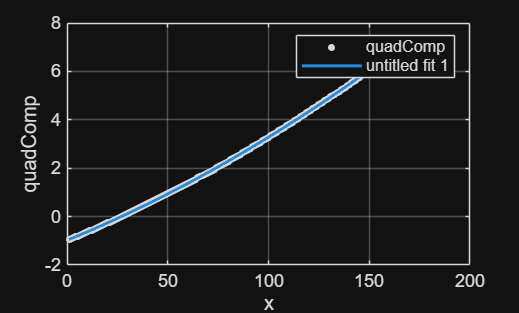

quad =      Linear model Poly2:
     quad(x) = p1*x^2 + p2*x + p3
     Coefficients (with 95% confidence bounds):
       p1 =   8.479e-05  (8.479e-05, 8.479e-05)
       p2 =     0.03415  (0.03415, 0.03415)
       p3 =     -0.9802  (-0.9802, -0.9802)

%now we fit models to the quad, cubic, and four trends for future
quad = quadModel(allComponents.quadComp)

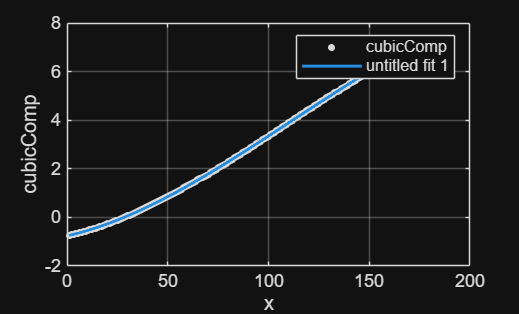

cubic = cubicModel(allComponents.cubicComp);

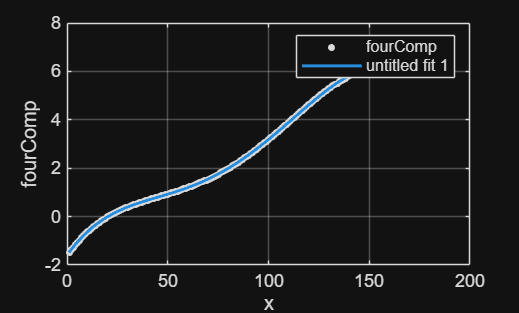

four = fourModel(allComponents.fourComp);

%analyze our arima_quad_31 model
model = arima_quad_31(quadRemainder)

model =   arima with properties:

     Description: "ARIMA(3,0,1) Model (Gaussian Distribution)"
      SeriesName: "Y"
    Distribution: Name = "Gaussian"
               P: 3
               D: 0
               Q: 1
        Constant: -0.00049479
              AR: {1.84215 -0.78395 -0.0649286} at lags [1 2 3]
             SAR: {}
              MA: {-1} at lag [1]
             SMA: {}
     Seasonality: 0
            Beta: [1×0]
        Variance: 0.0164852

%now predict data
frcst = table;
frcst.Time = training.Year

frcst = 163×1 table
    Time
    ____

    1856
    1857
    1858
    1859
    1860
    1861
    1862
    1863
    1864
    1865
    1866
    1867
    1868
    1869
    1870
    1871


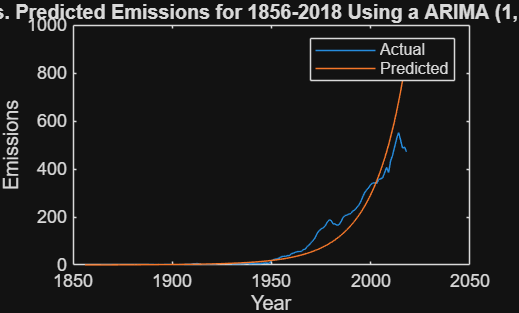

frcst.Idx = (1:163)';
frcstHorizon = height(frcst);
%ALE- LOOK HERE
y = quad(frcst.Idx);
frcst.fitComp = y;

[frcst.arimaFrcst, frcst.arimaResiduals] = forecast(model, frcstHorizon, quadRemainder);

%ALE - LOOK HERE
frcst.sumArima = frcst.fitComp + frcst.arimaFrcst;
frcst.totalArima = exp(frcst.sumArima);


figure;
plot(training.Year, training.Total,  "DisplayName", "Actual")
hold on
plot(frcst.Time, frcst.totalArima, "DisplayName", "Predicted")
xlabel("Year")
ylabel("Emissions")
title("Actual vs. Predicted Emissions for 1856-2018 Using a ARIMA (1, 0, 0) Model")
legend 
hold off


%now get error metrics
MetricsArima = table;

% Extract actual and forecasted values
actual = training.Total; %get from test data
forecasted = frcst.totalArima; %get from forecasted

% Calculate Root Mean Squared Error (RMSE) ->>> FIX
MetricsArima.RMSE = rmse(forecasted, actual);

% Calculate Root Relative Squared Error (RRSE)
MetricsArima.RRSE = sqrt(sum((forecasted - actual).^2) / sum((actual - mean(actual)).^2))

MetricsArima = 1×2 table
     RMSE      RRSE  
    ______    _______

    60.561    0.41837



%now try on testing data
frcsttest = table


frcsttest =

  0×0 empty table



frcsttest.Time = (2019:2023)'

frcsttest = 5×1 table
    Time
    ____

    2019
    2020
    2021
    2022
    2023


length(frcsttest.Time)

ans = 5

frcsttest

frcsttest = 5×1 table
    Time
    ____

    2019
    2020
    2021
    2022
    2023


frcsttest.Idx = (164:168)'

frcsttest = 5×2 table
    Time    Idx
    ____    ___

    2019    164
    2020    165
    2021    166
    2022    167
    2023    168


length(frcsttest.Idx)

ans = 5


frcsttest.fitComp = quad(frcsttest.Idx)

frcsttest = 5×3 table
    Time    Idx    fitComp
    ____    ___    _______

    2019    164    6.9016 
    2020    165    6.9636 
    2021    166    7.0258 
    2022    167    7.0882 
    2023    168    7.1508 



frcstHorizon = height(frcsttest)

frcstHorizon = 5

[frcsttest.ArimaFrcst, frcsttest.ArimaResiduals] = forecast(model, frcstHorizon, quadRemainder)

frcsttest = 5×5 table
    Time    Idx    fitComp    ArimaFrcst    ArimaResiduals
    ____    ___    _______    __________    ______________

    2019    164    6.9016      -0.65236        0.016485   
    2020    165    6.9636      -0.62937        0.028177   
    2021    166    7.0258      -0.60415        0.037886   
    2022    167    7.0882      -0.57767        0.045702   
    2023    168    7.1508      -0.55018         0.05188   


frcsttest = 5×5 table
    Time    Idx    fitComp    ArimaFrcst    ArimaResiduals
    ____    ___    _______    __________    ______________

    2019    164    6.9016      -0.65236        0.016485   
    2020    165    6.9636      -0.62937        0.028177   
    2021    166    7.0258      -0.60415        0.037886   
    2022    167    7.0882      -0.57767        0.045702   
    2023    168    7.1508      -0.55018         0.05188   


frcsttest.sumArima = frcsttest.fitComp + frcsttest.ArimaFrcst;
frcsttest.totalArima = exp(frcsttest.sumArima)

frcsttest = 5×7 table
    Time    Idx    fitComp    ArimaFrcst    ArimaResiduals    sumArima    totalArima
    ____    ___    _______    __________    ______________    ________    __________

    2019    164    6.9016      -0.65236        0.016485        6.2492        517.6  
    2020    165    6.9636      -0.62937        0.028177        6.3342       563.54  
    2021    166    7.0258      -0.60415        0.037886        6.4217       615.04  
    2022    167    7.0882      -0.57767        0.045702        6.5105       672.19  
    2023    168    7.1508      -0.55018         0.05188        6.6006       735.54  


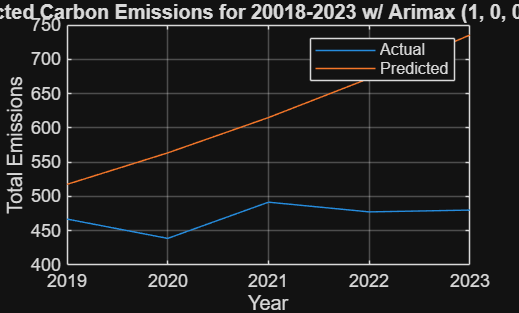


figure
plot(testing,"Year","Total", "DisplayName", "Actual")
hold on
plot(frcsttest,"Time","totalArima", "DisplayName", "Predicted")
xlabel("Year")
ylabel("Emissions")
grid on
title("Predicted Carbon Emissions for 20018-2023 w/ Arimax (1, 0, 0) Model")
ylabel("Total Emissions")
legend
hold off


combinedfrcst = frcst; frcsttest

frcsttest = 5×7 table
    Time    Idx    fitComp    ArimaFrcst    ArimaResiduals    sumArima    totalArima
    ____    ___    _______    __________    ______________    ________    __________

    2019    164    6.9016      -0.65236        0.016485        6.2492        517.6  
    2020    165    6.9636      -0.62937        0.028177        6.3342       563.54  
    2021    166    7.0258      -0.60415        0.037886        6.4217       615.04  
    2022    167    7.0882      -0.57767        0.045702        6.5105       672.19  
    2023    168    7.1508      -0.55018         0.05188        6.6006       735.54  


plot(combinedfrcst.Time, combinedfrcst.totalArima)
hold on
combinedog = training; testing

testing = 5×16 table
     Country      ISO3166_1Alpha_3    UNM49    Year    Total      Coal      Oil       Gas      Cement    Flaring    Other    PerCapita    Var13    Var14    Var15    Population
    __________    ________________    _____    ____    ______    ______    ______    ______    ______    _______    _____    _________    _____    _____    _____    __________

    {'Brazil'}        {'BRA'}          76      2019       467    61.888    299.44 

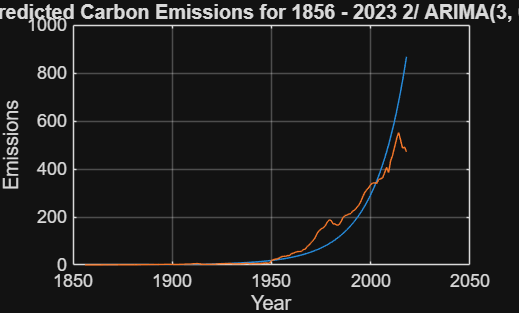

plot(combinedog.Year, combinedog.Total)
xlabel("Year")
ylabel("Emissions")
title("Predicted Carbon Emissions for 1856 - 2023 2/ ARIMA(3, 0, 1)")
grid on
hold off

%now get error metrics
% Create Metrics Table

MetricsArima = table;

% Extract actual and forecasted values
actual = testing.Total; %get from test data
forecasted = frcsttest.totalArima; %get from forecasted

% Calculate Root Mean Squared Error (RMSE) ->>> FIX
MetricsArima.RMSE = rmse(forecasted, actual);

% Calculate Root Relative Squared Error (RRSE)
MetricsArima.RRSE = sqrt(sum((forecasted - actual).^2) / sum((actual - mean(actual)).^2))

MetricsArima = 1×2 table
     RMSE      RRSE 
    ______    ______

    165.25    9.2342


%this is another cell doing the same as above. I used it to change the
%model
model = arima_quad_31(quadRemainder)

model =   arima with properties:

     Description: "ARIMA(3,0,1) Model (Gaussian Distribution)"
      SeriesName: "Y"
    Distribution: Name = "Gaussian"
               P: 3
               D: 0
               Q: 1
        Constant: -0.00049479
              AR: {1.84215 -0.78395 -0.0649286} at lags [1 2 3]
             SAR: {}
              MA: {-1} at lag [1]
             SMA: {}
     Seasonality: 0
            Beta: [1×0]
        Variance: 0.0164852

%now predict data
frcst = table;
frcst.Time = training.Year;
frcst.Idx = (1:163)';
frcstHorizon = height(frcst);

% CHANGE
y = quad(frcst.Idx)

y =    -0.9460
   -0.9116
   -0.8770
   -0.8422
   -0.8073
   -0.7722
   -0.7370
   -0.7015
   -0.6660
   -0.6302
   -0.5943
   -0.5582
   -0.5219
   -0.4854
   -0.4488


frcst.fitComp = y;
% CHANGE
[frcst.arimaFrcst, frcst.arimaResiduals] = forecast(model, frcstHorizon, quadRemainder);

frcst.sumArima = frcst.fitComp + frcst.arimaFrcst;
frcst.totalArima = exp(frcst.sumArima);


figure;
plot(training.Year, training.Total,  "DisplayName", "Actual")
hold on
plot(frcst.Time, frcst.totalArima, "DisplayName", "Predicted")
xlabel("Year")
ylabel("Emissions")
title("Actual vs. Predicted Emissions for 1856-2018 Using a ARIMA (1, 0, 0) Model")
legend 
hold off


%now get error metrics
MetricsArima = table;

% Extract actual and forecasted values
actual = training.Total; %get from test data
forecasted = frcst.totalArima; %get from forecasted

% Calculate Root Mean Squared Error (RMSE) ->>> FIX
MetricsArima.RMSE = rmse(forecasted, actual);

% Calculate Root Relative Squared Error (RRSE)
MetricsArima.RRSE = sqrt(sum((forecasted - actual).^2) / sum((actual - mean(actual)).^2))

MetricsArima = 1×2 table
     RMSE      RRSE  
    ______    _______

    60.561    0.41837



%now try on testing data
frcsttest = table


frcsttest =

  0×0 empty table



frcsttest.Time = testing.Year

frcsttest = 5×1 table
    Time
    ____

    2019
    2020
    2021
    2022
    2023


frcsttest.Idx = (164:168)' %increase this to go up to 2050

frcsttest = 5×2 table
    Time    Idx
    ____    ___

    2019    164
    2020    165
    2021    166
    2022    167
    2023    168



frcstHorizon = height(frcsttest)

frcstHorizon = 5

y = quad(frcsttest.Idx)

y =     6.9016
    6.9636
    7.0258
    7.0882
    7.1508


frcsttest.fitComp = y

frcsttest = 5×3 table
    Time    Idx    fitComp
    ____    ___    _______

    2019    164    6.9016 
    2020    165    6.9636 
    2021    166    7.0258 
    2022    167    7.0882 
    2023    168    7.1508 



[frcsttest.ArimaFrcst, frcsttest.ArimaResiduals] = forecast(model, frcstHorizon, quadRemainder)

frcsttest = 5×5 table
    Time    Idx    fitComp    ArimaFrcst    ArimaResiduals
    ____    ___    _______    __________    ______________

    2019    164    6.9016      -0.65236        0.016485   
    2020    165    6.9636      -0.62937        0.028177   
    2021    166    7.0258      -0.60415        0.037886   
    2022    167    7.0882      -0.57767        0.045702   
    2023    168    7.1508      -0.55018         0.05188   


frcsttest = 5×5 table
    Time    Idx    fitComp    ArimaFrcst    ArimaResiduals
    ____    ___    _______    __________    ______________

    2019    164    6.9016      -0.65236        0.016485   
    2020    165    6.9636      -0.62937        0.028177   
    2021    166    7.0258      -0.60415        0.037886   
    2022    167    7.0882      -0.57767        0.045702   
    2023    168    7.1508      -0.55018         0.05188   


frcsttest.sumArima = frcsttest.fitComp + frcsttest.ArimaFrcst;
frcsttest.totalArima = exp(frcsttest.sumArima)

frcsttest = 5×7 table
    Time    Idx    fitComp    ArimaFrcst    ArimaResiduals    sumArima    totalArima
    ____    ___    _______    __________    ______________    ________    __________

    2019    164    6.9016      -0.65236        0.016485        6.2492        517.6  
    2020    165    6.9636      -0.62937        0.028177        6.3342       563.54  
    2021    166    7.0258      -0.60415        0.037886        6.4217       615.04  
    2022    167    7.0882      -0.57767        0.045702        6.5105       672.19  
    2023    168    7.1508      -0.55018         0.05188        6.6006       735.54  


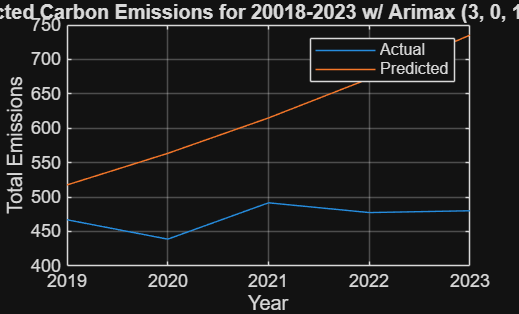


figure
plot(testing,"Year","Total", "DisplayName", "Actual")
hold on
plot(frcsttest,"Time","totalArima", "DisplayName", "Predicted")
xlabel("Year")
ylabel("Emissions")
grid on
title("Predicted Carbon Emissions for 20018-2023 w/ Arimax (3, 0, 1) Model")
ylabel("Total Emissions")
legend
hold off

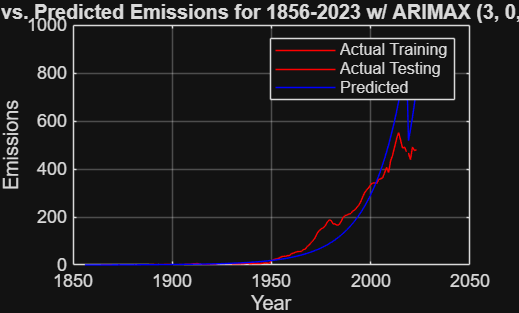

%combine the frcst.totalArima and frcsttest.totalArima columns 
combinedTotal = [frcst.totalArima; frcsttest.totalArima];
%combine the frcst.Time and frcsttest.Time columns
combinedTime = [frcst.Time; frcsttest.Time];
figure
plot(training.Year, training.Total, "r", "DisplayName", "Actual Training")
hold on
plot(testing.Year, testing.Total, "r", "DisplayName", "Actual Testing")

plot(combinedTime, combinedTotal, "b", "DisplayName", "Predicted")
%plot(frcst.Time, frcst.totalArima, "g", "DisplayName", "Predicted Training")
%plot(frcsttest.Time, frcsttest.totalArima, "g", "DisplayName", "Predicted Testing")
xlabel("Year")
ylabel("Emissions")
title("Actual vs. Predicted Emissions for 1856-2023 w/ ARIMAX (3, 0, 1) Model")
legend 
grid on
hold off

%now get error metrics
% Create Metrics Table


MetricsArima = table;

% Extract actual and forecasted values
%extract rows 1, 3, 4, 5 from the testing.Total column
% Extract specific rows from the testing.Total column
selectedRows = [1, 3, 4, 5];
actual2 = testing.Total(selectedRows);
forecasted2 = frcsttest.totalArima(selectedRows);

actual = testing.Total 

actual =   466.9978
  438.8161
  491.6249
  477.4486
  480.0781


forecasted = frcsttest.totalArima %get from forecasted

forecasted =   517.6009
  563.5423
  615.0387
  672.1933
  735.5387




MetricsArima.RMSE = rmse(forecasted, actual);
MetricsARIMA.RMSE2 = rmse(forecasted2, actual2)

MetricsARIMA = struct with fields:
    RMSE2: 173.9089



% Calculate Root Relative Squared Error (RRSE)
MetricsArima.RRSE = sqrt(sum((forecasted - actual).^2) / sum((actual - mean(actual)).^2))

MetricsArima = 1×2 table
     RMSE      RRSE 
    ______    ______

    165.25    9.2342
